### Step 0 加载并绘制原始mri图像

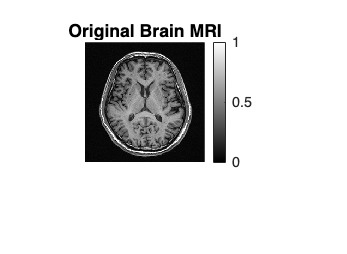

data = load('../data/Lab4_2025_MRI.mat');
variableNames = fieldnames(data);
mriData = data.(variableNames{1}); 
mriData = mat2gray(mriData);

figure;
imshow(mriData, []);
colormap gray;
colorbar;
title('Original Brain MRI');

## Project 3 restoration

### Step 1 设置不同D0的高斯滤波

• Blurring the image with a Guassian filter in the **frequency domain** —Set different D0

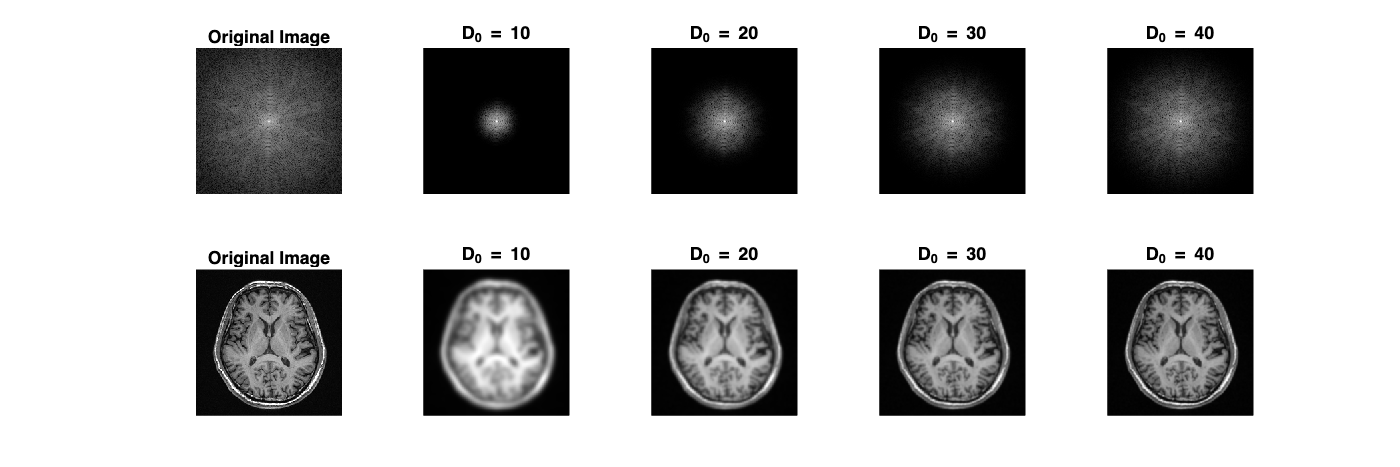

figure('Position', [100, 100, 1200, 400]);

D0_values = [10, 20, 30, 40];

% 原始图像的频域
F = fft2(mriData);
F_shifted = fftshift(F);
F_magnitude = log(1 + abs(F_shifted));

subplot(2, 5, 1);
imshow(F_magnitude, []);
title('Original Image');

subplot(2, 5, 6);
imshow(mriData, []);
title('Original Image');

% 对不同的D0值进行处理
for i = 1:length(D0_values)
    D0 = D0_values(i);
    
    % 创建高斯低通滤波器
    [M, N] = size(mriData);
    u = (-floor(M/2):ceil(M/2)-1);
    v = (-floor(N/2):ceil(N/2)-1);
    [U, V] = meshgrid(u, v);
    D = sqrt(U.^2 + V.^2);
    H = exp(-(D.^2) / (2 * D0^2));
    
    % 在频域应用滤波器
    F_filtered = F_shifted .* H;
    
    subplot(2, 5, i + 1);
    imshow(log(1 + abs(F_filtered)), []);
    title(['D_0 = ', num2str(D0)]);
    
    % 逆傅里叶变换
    F_filtered_unshifted = ifftshift(F_filtered);
    filtered_image = ifft2(F_filtered_unshifted);
    
    % 归一化处理
    filtered_image = mat2gray(real(filtered_image));
    filtered_image = uint8(filtered_image * 255);
    
    subplot(2, 5, i + 6);
    imshow(filtered_image, []);
    title(['D_0 = ', num2str(D0)]);
end     

### Step 2 加入Rician 噪声

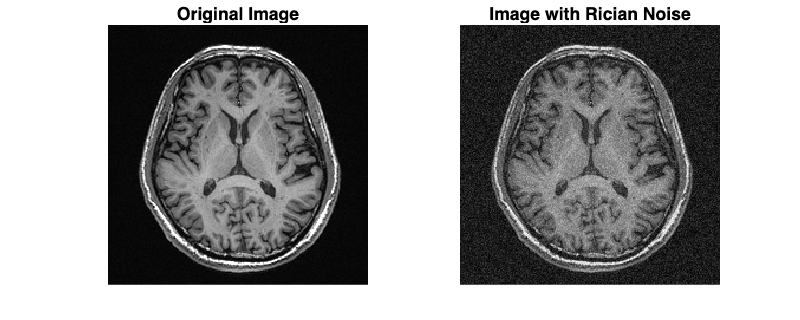

 % 定义Rician噪声的参数
nu = 0; % 信号分量
sigma = 0.1; % 噪声标准差

% 定义Rician概率密度函数
pdf_rician = @(x) (x./(sigma^2)).*exp(-(x.^2 + nu^2)./(2*sigma^2)).*besseli(0, (x.*nu)./(sigma^2));

% 找到pdf的最大值用于接受 - 拒绝采样
x_range = linspace(0, 3*sigma, 1000);
pdf_max = max(pdf_rician(x_range));

% 生成与图像大小相同的Rician噪声
noisy_shape = size(mriData);
rician_noise = zeros(noisy_shape);
for i = 1:numel(rician_noise)
    while true
        % 生成均匀分布的x和y
        x = rand() * 3*sigma;
        y = rand() * pdf_max;
        % 接受 - 拒绝准则
        if y <= pdf_rician(x)
            rician_noise(i) = x;
            break;
        end
    end
end

% 添加Rician噪声到原始图像
noisy_image = mriData + rician_noise;

% 归一化处理
noisy_image = mat2gray(noisy_image);

% 创建一个1行2列的图形窗口
figure('Position', [100, 100, 500, 200]);

% 显示原始图像
subplot(1, 2, 1);
imshow(mriData, []);
title('Original Image');

% 显示添加Rician噪声后的图像
subplot(1, 2, 2);
imshow(noisy_image, []);
title('Image with Rician Noise'); 

### Step 3 图像恢复

• Suppose the blurring kernel is known, restore the image with the following method

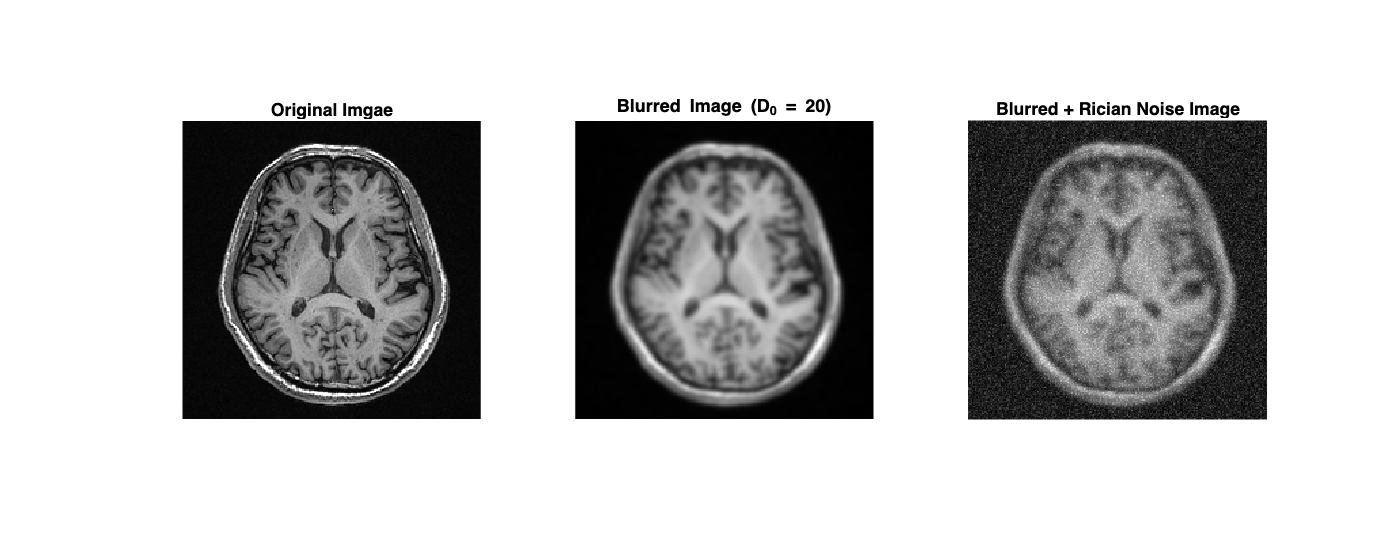

% Step 1: 频域高斯模糊（以 D0=20 为例）
D0 = 20;
[M, N] = size(mriData);
u = (-floor(M/2):ceil(M/2)-1);
v = (-floor(N/2):ceil(N/2)-1);
[U, V] = meshgrid(u, v);
D = sqrt(U.^2 + V.^2);
H = exp(-(D.^2) / (2 * D0^2)); % 高斯低通滤波器

% 频域处理
F = fft2(mriData);
F_shifted = fftshift(F);
F_filtered = F_shifted .* H;
F_filtered_unshifted = ifftshift(F_filtered);
blurred_image = ifft2(F_filtered_unshifted);
blurred_image = real(blurred_image); % 取实部（避免极小虚数干扰）

% Step 2: 添加 Rician 噪声
sigma = 0.1; % 噪声标准差
e_real = normrnd(0, sigma, size(blurred_image)); % 实部噪声
e_imag = normrnd(0, sigma, size(blurred_image)); % 虚部噪声
noisy_image = blurred_image + sqrt((0 + e_real).^2 + e_imag.^2); % nu=0 时的 Rician 噪声

% 显示结果
figure('Position', [100, 100, 1000, 400]);
subplot(1, 3, 1);
imshow(mriData, []);
title('Original Imgae');
subplot(1, 3, 2);
imshow(blurred_image, []);
title('Blurred Image (D_0 = 20)');
subplot(1, 3, 3);
imshow(noisy_image, []);
title('Blurred + Rician Noise Image');

– Inverse filter

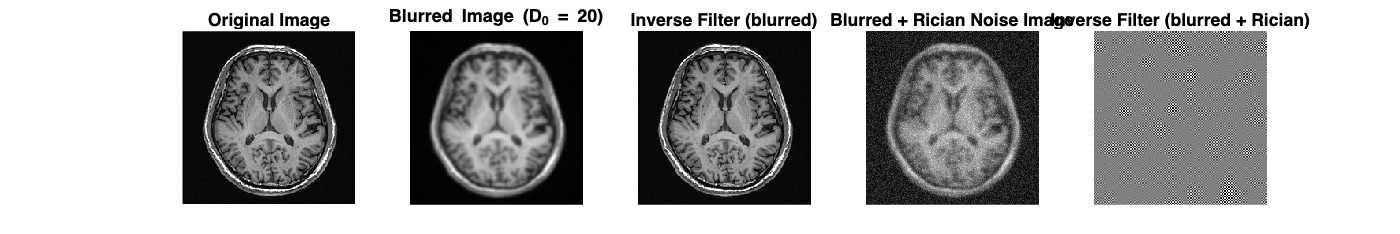

% 生成高斯低通滤波器 H
[M, N] = size(mriData);
u = (-floor(M/2):ceil(M/2)-1);
v = (-floor(N/2):ceil(N/2)-1);
[U, V] = meshgrid(u, v);
D = sqrt(U.^2 + V.^2);
D0 = 20;
H = exp(-(D.^2) / (2 * D0^2));

% 对含噪模糊图像进行傅里叶变换
F_noisy = fft2(noisy_image);
F_noisy_shifted = fftshift(F_noisy);

% 计算逆滤波器
H_inverse = 1 ./ H;
% 处理 H 中为 0 的元素，避免除零错误
H_inverse(H == 0) = 0;

% 在频域应用逆滤波器
F_restored_shifted = F_noisy_shifted .* H_inverse;

% 逆傅里叶变换
F_restored = ifftshift(F_restored_shifted);
restored_image = ifft2(F_restored);
restored_image = real(restored_image); % 取实部
restored_image = mat2gray(restored_image); % 归一化

% 对无噪声的模糊图像进行傅里叶变换
F_blurred = fft2(blurred_image);
F_blurred_shifted = fftshift(F_blurred);

% 在频域应用逆滤波器到无噪声的模糊图像
F_restored_shifted_no_noise = F_blurred_shifted .* H_inverse;

% 逆傅里叶变换
F_restored_no_noise = ifftshift(F_restored_shifted_no_noise);
restored_image_no_noise = ifft2(F_restored_no_noise);
restored_image_no_noise = real(restored_image_no_noise); % 取实部
restored_image_no_noise = mat2gray(restored_image_no_noise); % 归一化

figure('Position', [100, 100, 1200,200]);
subplot(1, 5, 1);
imshow(mriData, []);
title('Original Image');
subplot(1, 5, 2);
imshow(blurred_image, []);
title('Blurred Image (D_0 = 20)');
subplot(1, 5, 3);
imshow(restored_image_no_noise, []);
title('Inverse Filter (blurred)');
subplot(1, 5, 4);
imshow(noisy_image, []);
title('Blurred + Rician Noise Image');
subplot(1, 5, 5);
imshow(restored_image, []);
title('Inverse Filter (blurred + Rician)'); 

– Limited inverse filter

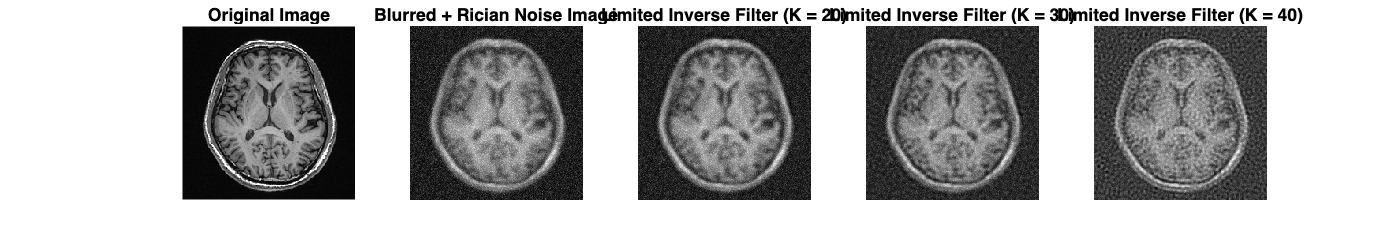

% 生成高斯低通滤波器 H
[M, N] = size(mriData);
u = (-floor(M/2):ceil(M/2)-1);
v = (-floor(N/2):ceil(N/2)-1);
[U, V] = meshgrid(u, v);
D = sqrt(U.^2 + V.^2);
D0 = 20;
H = exp(-(D.^2) / (2 * D0^2));

% 对含噪模糊图像进行傅里叶变换
F_noisy = fft2(noisy_image);
F_noisy_shifted = fftshift(F_noisy);

% 计算逆滤波器
H_inverse = 1 ./ H;
% 处理 H 中为 0 的元素，避免除零错误
H_inverse(H == 0) = 0;

% 在频域应用逆滤波器
F_restored_shifted = F_noisy_shifted .* H_inverse;

% 逆傅里叶变换
F_restored = ifftshift(F_restored_shifted);
restored_image = ifft2(F_restored);
restored_image = real(restored_image); % 取实部
restored_image = mat2gray(restored_image); % 归一化

% 对无噪声的模糊图像进行傅里叶变换
F_blurred = fft2(blurred_image);
F_blurred_shifted = fftshift(F_blurred);

% 在频域应用逆滤波器到无噪声的模糊图像
F_restored_shifted_no_noise = F_blurred_shifted .* H_inverse;

% 逆傅里叶变换
F_restored_no_noise = ifftshift(F_restored_shifted_no_noise);
restored_image_no_noise = ifft2(F_restored_no_noise);
restored_image_no_noise = real(restored_image_no_noise); % 取实部
restored_image_no_noise = mat2gray(restored_image_no_noise); % 归一化

% 有限逆滤波参数
K_values = [20, 30, 40];
restored_images_limited = cell(1, length(K_values));

for i = 1:length(K_values)
    K = K_values(i);
    % 生成有限逆滤波器
    H_limited = H;
    H_limited(D > K) = 1;
    H_limited_inverse = 1 ./ H_limited;
    H_limited_inverse(H_limited == 0) = 0;
    
    % 在频域应用有限逆滤波器
    F_restored_shifted_limited = F_noisy_shifted .* H_limited_inverse;
    
    % 逆傅里叶变换
    F_restored_limited = ifftshift(F_restored_shifted_limited);
    restored_image_limited = ifft2(F_restored_limited);
    restored_image_limited = real(restored_image_limited); % 取实部
    restored_image_limited = mat2gray(restored_image_limited); % 归一化
    
    restored_images_limited{i} = restored_image_limited;
end

% 显示结果
figure('Position', [100, 100, 1200, 200]);
subplot(1, 5, 1);
imshow(mriData, []);
title('Original Image');
subplot(1, 5, 2);
imshow(noisy_image, []);
title('Blurred + Rician Noise Image');
for i = 1:length(K_values)
    subplot(1, 5, i + 2);
    imshow(restored_images_limited{i}, []);
    title(['Limited Inverse Filter (K = ', num2str(K_values(i)), ')']);
end    

– Wiener filter 

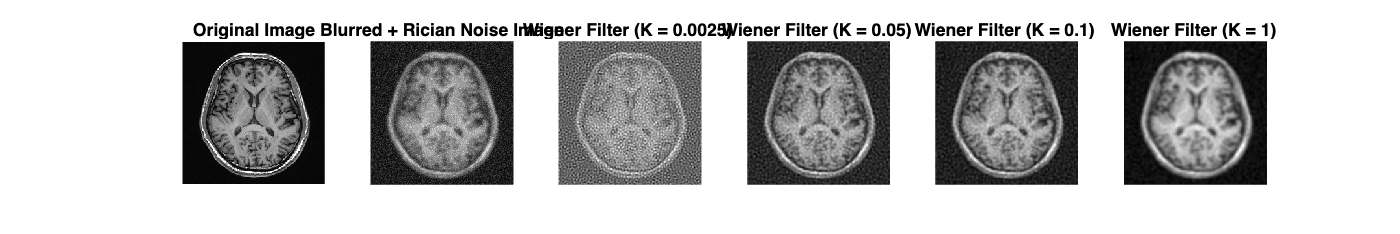

% 生成高斯低通滤波器 H
[M, N] = size(mriData);
u = (-floor(M/2):ceil(M/2)-1);
v = (-floor(N/2):ceil(N/2)-1);
[U, V] = meshgrid(u, v);
D = sqrt(U.^2 + V.^2);
D0 = 20;
H = exp(-(D.^2) / (2 * D0^2));

% 对含噪模糊图像进行傅里叶变换
F_noisy = fft2(noisy_image);
F_noisy_shifted = fftshift(F_noisy);

% 计算逆滤波器
H_inverse = 1 ./ H;
% 处理 H 中为 0 的元素，避免除零错误
H_inverse(H == 0) = 0;

% 在频域应用逆滤波器
F_restored_shifted = F_noisy_shifted .* H_inverse;

% 逆傅里叶变换
F_restored = ifftshift(F_restored_shifted);
restored_image = ifft2(F_restored);
restored_image = real(restored_image); % 取实部
restored_image = mat2gray(restored_image); % 归一化

% 对无噪声的模糊图像进行傅里叶变换
F_blurred = fft2(blurred_image);
F_blurred_shifted = fftshift(F_blurred);

% 在频域应用逆滤波器到无噪声的模糊图像
F_restored_shifted_no_noise = F_blurred_shifted .* H_inverse;

% 逆傅里叶变换
F_restored_no_noise = ifftshift(F_restored_shifted_no_noise);
restored_image_no_noise = ifft2(F_restored_no_noise);
restored_image_no_noise = real(restored_image_no_noise); % 取实部
restored_image_no_noise = mat2gray(restored_image_no_noise); % 归一化

% 有限逆滤波参数
K_values = [20, 30, 40];
restored_images_limited = cell(1, length(K_values));

for i = 1:length(K_values)
    K = K_values(i);
    % 生成有限逆滤波器
    H_limited = H;
    H_limited(D > K) = 1;
    H_limited_inverse = 1 ./ H_limited;
    H_limited_inverse(H_limited == 0) = 0;
    
    % 在频域应用有限逆滤波器
    F_restored_shifted_limited = F_noisy_shifted .* H_limited_inverse;
    
    % 逆傅里叶变换
    F_restored_limited = ifftshift(F_restored_shifted_limited);
    restored_image_limited = ifft2(F_restored_limited);
    restored_image_limited = real(restored_image_limited); % 取实部
    restored_image_limited = mat2gray(restored_image_limited); % 归一化
    
    restored_images_limited{i} = restored_image_limited;
end

% 维纳滤波参数
K_wiener_values = [0.0025, 0.05, 0.1, 1];
restored_images_wiener = cell(1, length(K_wiener_values));

for i = 1:length(K_wiener_values)
    K_wiener = K_wiener_values(i);
    % 生成维纳滤波器
    H_wiener = conj(H) ./ (abs(H).^2 + K_wiener);
    
    % 在频域应用维纳滤波器
    F_restored_shifted_wiener = F_noisy_shifted .* H_wiener;
    
    % 逆傅里叶变换
    F_restored_wiener = ifftshift(F_restored_shifted_wiener);
    restored_image_wiener = ifft2(F_restored_wiener);
    restored_image_wiener = real(restored_image_wiener); % 取实部
    restored_image_wiener = mat2gray(restored_image_wiener); % 归一化
    
    restored_images_wiener{i} = restored_image_wiener;
end

% 显示结果
figure('Position', [100, 100, 1800, 300]);
subplot(1, 6, 1);
imshow(mriData, []);
title('Original Image');
subplot(1, 6, 2);
imshow(noisy_image, []);
title('Blurred + Rician Noise Image');
for i = 1:length(K_wiener_values)
    subplot(1, 6, i + 2);
    imshow(restored_images_wiener{i}, []);
    title(['Wiener Filter (K = ', num2str(K_wiener_values(i)), ') ']);
end    